## Domain and Method

addpath('Subroutines') % the functions are all stored in the subfolder 'Subroutines'
clear

We want to solve the Monge-Ampere on a rectangle $\Omega =\left(\textrm{x0},\textrm{x1}\right)\times \left(\textrm{y0},\textrm{y1}\right)$ using a monotonic wid-stencil scheme. For simplicity, we make it a square centered at the origin. 

We typically define the exerior boundary as $\Sigma :=\partial \Omega$.   

x0 = -1; x1 = 1;
y0 = -1; y1 = 1;

padding = 0.2;
lims = [x0-padding, x1+padding, y0-padding, y1+padding]; % useful for plotting

We can choose the granularity of the mesh is controlled by the variable `N`. 

The stencil width $d$ of the difference scheme is controlled by the variable `depth`. The figure below shows the wide stencil with $d=2$. 

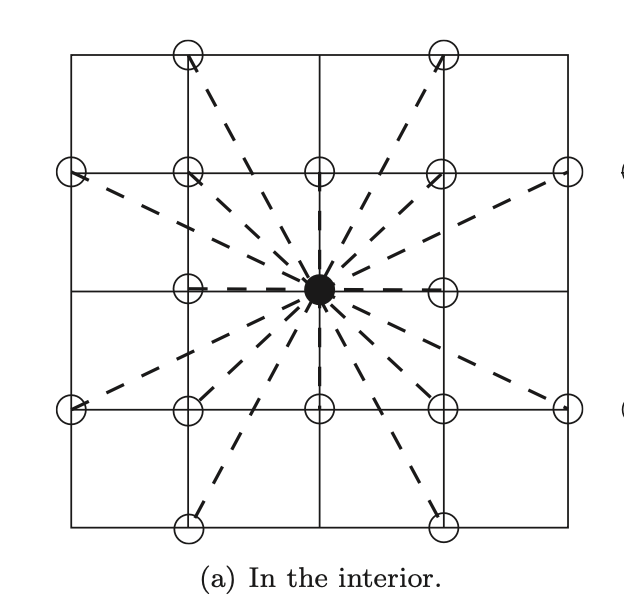

## Mesh

% Parameters needed to generate grid
N = 2^3+1;
h = (x1-x0)/(N+1);
depth = 2;

A special mesh must be made for the wide stencil scheme. The interior $\Omega$ and the boundary $\Gamma =\partial \Omega$ are meshed differently. The subroutine `buildMesh_Rect` creates the mesh. The subroutine returns information about the node coordinates. 

[Points,Interior,Boundary,NMatSDD,CMatSDD,theta] = buildMesh_Rect(x0,x1,y0,y1,h,depth);
% OUTPUT:
% Points - (Np x 2) arrary of node coordinates
% Interior - (1 x Ni) interior node indicator
% Boundary - (Nb x 1) boundary node indicator
% NMatSDD - (Ni x Ns*3) node adjcacency info
% CMatSDD - (Ni x Ns*3) FD coefficient info
% theta - (Ns x 1) angular position of stencil points
Np = length(Points);
Ni = Interior(end);
Nb = length(Boundary);
Ns = length(theta);
fprintf('Np = %d\nNi = %d\nNb = %d\nNs = %d',Np,Ni,Nb,Ns)

Np = 193
Ni = 81
Nb = 112
Ns = 9

Let $N_p$ be the total number of points on the mesh. $N_i$ will be the number of points in the interior, $N_b$ will be the number of points on the boundary and $N_p =N_i +N_b$. 

The number of stencil points for a given point including the middle is given by $N_{\textrm{sp}}$. It depends on stencil width. For example, if `depth`=1, then $N_s =9$.  

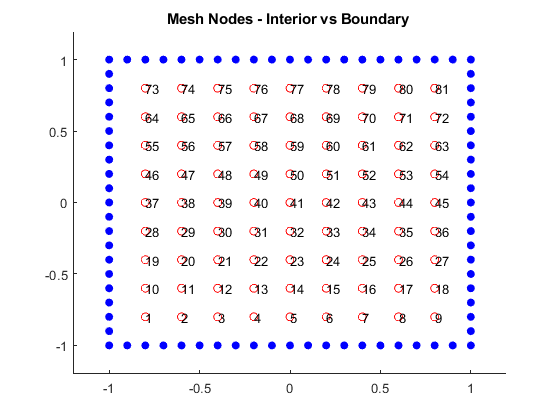

figure
hold on
scatter(Points(Interior,1),Points(Interior,2),[],'r')
scatter(Points(Boundary,1),Points(Boundary,2),[],'b','filled')
title('Mesh Nodes - Interior vs Boundary ')
xi = Points(Interior,1);
yi = Points(Interior,2);
hold on
for i = 1:Ni
    text(xi(i),yi(i),num2str(i))
end
axis(lims)

The plot above shows the mesh nodes. The interior nodes (marked in red) are spaced out in intervals of $h=\frac{\textrm{x1}-\textrm{x0}}{N+1}$.The interior nodes are numbered in the natural ordering. There are $N$ nodes per row. We can use this structure to determine local neighboring interior nodes.   

The boundary nodes (marked in blue) are spaced differently from the interior nodes depending on the stencil width.  

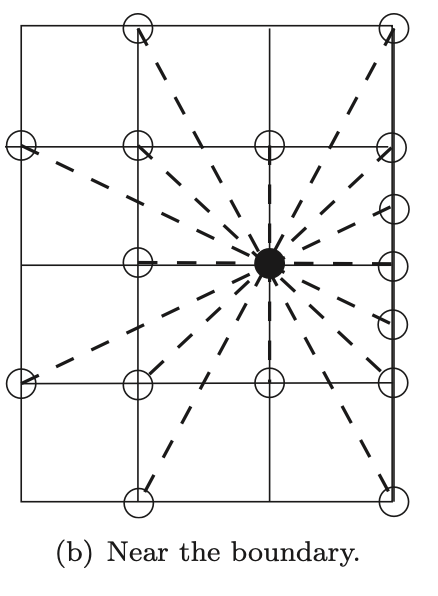

The figure above shows the wide stencil near the boundary. When near the boundary, the stencil nodes are projected onto the boundary in a way that preserves the angle. 

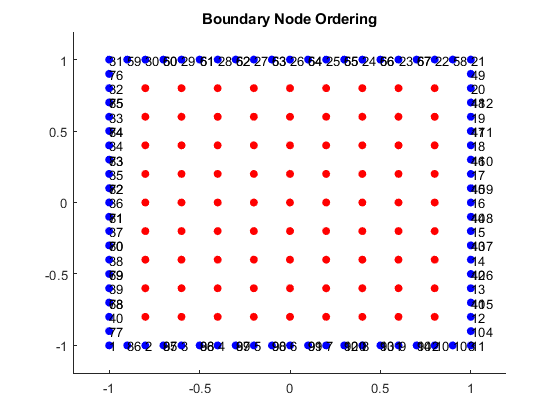

figure
hold on
scatter(Points(Interior,1),Points(Interior,2),[],'r','filled')
scatter(Points(Boundary,1),Points(Boundary,2),[],'b','filled')
title('Boundary Node Ordering')
xi = Points(Boundary,1);
yi = Points(Boundary,2);
hold on
for i = 1:Nb
    text(xi(i),yi(i),num2str(i))
end
axis(lims)
hold off

The plot above shows how the boundary nodes are ordered. 

## NMatSSD

Every interior node has $N_s -1$ neighboring nodes which influence its derivative approximation. The information is stored in `NMatSSD`. The $i^{\textrm{th}}$ row of the `NMatSSD` matrix corresponds to the list of neighbors of node $x_i$. They are listed in terms of the index of the nodes listed in matrix `Points`. The columns of `NMatSSD` are stored in groups of 3. The number of columns is ${3N}_s$. The first column in each set of 3 is the center node $x_i$. The following 2 columns correspond to the node in direction $\theta$ and the opposite direction $\theta^{\sim } =\theta +\pi$. 

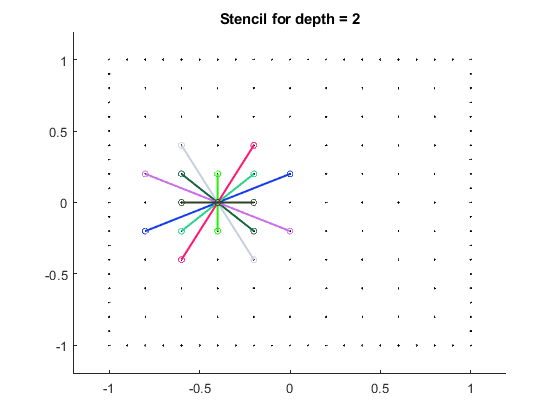

ind = 4*N + 3;
row = NMatSDD(ind,:);

figure
scatter(Points(:,1),Points(:,2),1,'k')
hold on
for i = 1:Ns
    c = rand(1,3); % random color
    pts = Points( row((1:3)+(i-1)*3),:);
    plot(pts(:,1),pts(:,2),'color',c,'LineWidth',1.5)
    scatter(pts(:,1),pts(:,2),20,c)
end
title("Stencil for depth = "+depth)

axis(lims)

The plot above shows the stencil centered at an interior mesh node. Each line color corresponds to a column triplet. 

## Domain Decomposition

Let's begin with 2 subdomains. We will split the domain horizontally along the x-asix. The bottom half is $\Omega_1 =\left(\textrm{x0},\textrm{x1}\right)\times \left(\textrm{y0},0\right)$ and the top is $\Omega_2 =\left(\textrm{x0},\textrm{x1}\right)\times \left(0,\textrm{y1}\right)$.

We will create 2 subarrays of `Boundary` and `Interior `as well as an `Interface` array for the nodes on the artificial interface. 

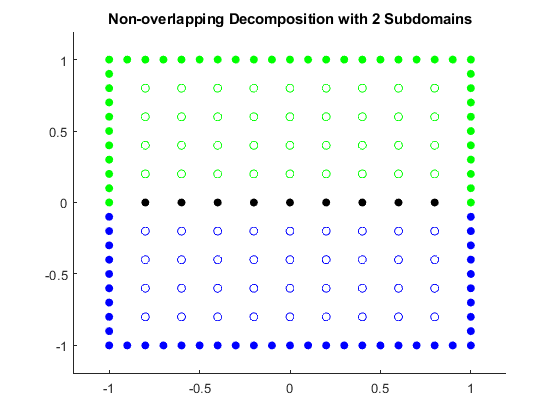

Interface = find(Points(Interior,2)==0); % points in the interior that lie on the artificial interface
Interior1 = Interior(Points(Interior,2)<0);
Interior2 = Interior(Points(Interior,2)>0);
Boundary1 = Boundary(Points(Boundary,2)<=0);
Boundary2 = Boundary(Points(Boundary,2)>=0);

figure
hold on
c1 = [0 0 1];
c2 = [0 1 0];
scatter(Points(Interior1,1),Points(Interior1,2),[],c1)
scatter(Points(Boundary1,1),Points(Boundary1,2),[],c1,'filled')

scatter(Points(Interior2,1),Points(Interior2,2),[],c2)
scatter(Points(Boundary2,1),Points(Boundary2,2),[],c2,'filled')

scatter(Points(Interface,1),Points(Interface,2),[],[0 0 0],'filled')
axis(lims)
title('Non-overlapping Decomposition with 2 Subdomains')

The plot above shows the non-overlapping domain decomposition. The domains are color coded in blue and green. The solid circles are interfaces and the open circles are interior nodes. The main issue with this decomposition is that the mesh along the artificial interface is supposed to act as a boundary. However, the mesh along the exterior domain is different than the interior nodes. This must be remedied by sampling points from the neighbor. 

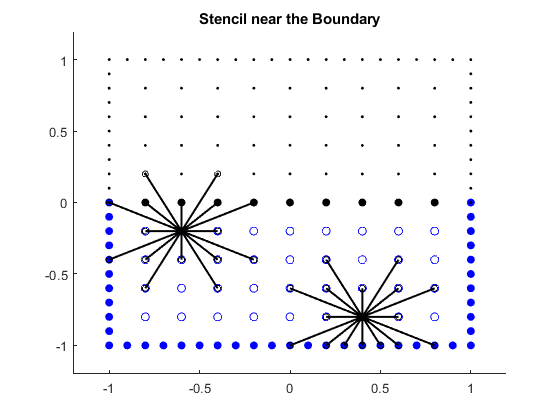

figure
hold on
c1 = [0 0 1];
c2 = [0 1 0];
scatter(Points(Interior1,1),Points(Interior1,2),[],c1)
scatter(Points(Boundary1,1),Points(Boundary1,2),[],c1,'filled')

scatter(Points(Interior2,1),Points(Interior2,2),5,'k','filled')
scatter(Points(Boundary2,1),Points(Boundary2,2),5,'k','filled')

scatter(Points(Interface,1),Points(Interface,2),[],[0 0 0],'filled')

% plot stencil near artificial boundary
ind = 3*N + 2;
row = NMatSDD(ind,:);
for i = 1:Ns
    c = 'k';
    pts = Points( row((1:3)+(i-1)*3),:);
    plot(pts(:,1),pts(:,2),'color',c,'LineWidth',1.5)
    scatter(pts(:,1),pts(:,2),20,c)
end

% plot stencil near artificial boundary
ind = 7;
row = NMatSDD(ind,:);
for i = 1:Ns
    c = 'k';
    pts = Points( row((1:3)+(i-1)*3),:);
    plot(pts(:,1),pts(:,2),'color',c,'LineWidth',1.5)
    scatter(pts(:,1),pts(:,2),20,c)
end

title('Stencil near the Boundary')
axis(lims)

The plot above shows the stencil near of the scheme for 2 points near the boundary. The node near the exterior boundary will not give any additional complications. The node near the artificial boundary, however, has stencil points extending over to the other subdomain. The plot above shows a stencil with `depth`=2. The node near the artificial interface is extending its stencil 1 layer above the interface. In general, the thickness of the sampling region is `depth`-1 layers thick. Therefor, if we use `depth`=1, then we would not need to anything special because the stencil will not extend over to the other side. 

## Overlapping Domains 

In general, we want some overlap between the 2 regions.  

We want to do an overlapping domain decomposition, which means we extend our non-overlapping domains from $\Omega_i$ to $\Omega_i^*$. The overlap is controlled with a positive integer $\delta$. $\delta \;$correponds to the number of layers of nodes that each domain extends over the artificial interface. So $\delta =0$ corresponds to $\Omega_i =\Omega_i^*$ which means the overlapping region is 1 layer thick. In general the overlapping region consists of $2\delta +1$ layers of nodes.

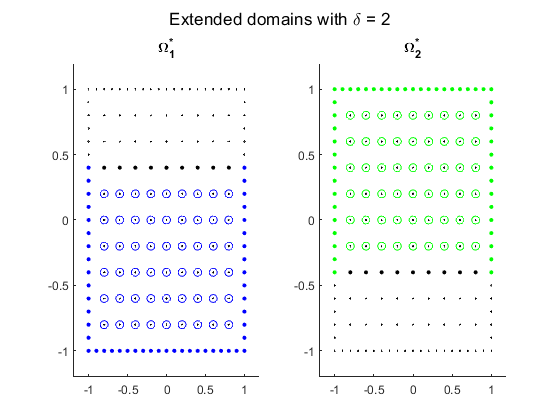

delta = 2;
Boundary1 = Boundary(Points(Boundary,2) <= h*delta); % extend upward
Boundary2 = Boundary(Points(Boundary,2) >= -h*delta); % extend downward
Interface1 = Interface+N*delta;
Interface2 = Interface-N*delta;

for i = 1:delta
    Interior1 = [Interior1, Interface'+N*(i-1)];
    Interior2 = [Interior2, Interface'-N*(i-1)];
end

figure
subplot(121)
scatter(Points(:,1),Points(:,2),1,'k')
hold on
scatter(Points(Interior1,1),Points(Interior1,2),[],c1)
scatter(Points(Boundary1,1),Points(Boundary1,2),10,c1,"filled")
scatter(Points(Interface1,1),Points(Interface1,2),10,"black","filled")
axis(lims)
title('\Omega_1^{*}')

subplot(122)
scatter(Points(:,1),Points(:,2),1,'k')
hold on
scatter(Points(Interior2,1),Points(Interior2,2),[],c2)
scatter(Points(Boundary2,1),Points(Boundary2,2),10,c2,'filled')
scatter(Points(Interface2,1),Points(Interface2,2),10,"black","filled")
hold off
axis(lims)
title('\Omega_2^{*}')
sgtitle("Extended domains with \delta = "+delta)

The plot above shows the extended domains with $\delta =2$. The two domains have 3 layers of interior nodes in common. 

## Schwarz Alternating Procedure 

We will discuss our test method. Let us choose a stencil with of 2 and we choose an overlap $\delta =1$. 

Let us define the boundary of $\Omega_i^*$ that extends over $\Omega_j$ as $\Sigma_{\textrm{ij}} =\partial \Omega_i^* \cap \Omega_j$. Let us define $\Sigma_{\textrm{ij}}^h$ as the discretization of $\Sigma_{\textrm{ij}}$. The set of points in $\Sigma_{\textrm{ij}}^h$ will inclued both the points that lie on $\Sigma_{\textrm{ij}}$ as well as the points outside of $\Omega_i^*$ that complete the stencil. All points on $\Sigma_{\textrm{ij}}^h$ will be color coded as black. 

Let us also define $\Sigma_i =\partial \Omega_i^* \cap \Sigma$ and subsequently $\Sigma_i^h$ as its discretization. 

Let $f\left(x,y\right)=\left(1+x^2 +y^2 \right)e^{x^2 +y^2 }$ and $g\left(x,y\right)=e^{\frac{x^2 +y^2 }{2}}$. Then our global problem is 


$$\left\lbrace \begin{array}{ll}
\textrm{det}\left(D^2 u\right)=f & \left(x,y\right)\in \Omega \\
u=g & \left(x,y\right)\in \Sigma 
\end{array}\;\ldotp \right.$$


Our iterative scheme will be: 

`    Set `$u_1^{\left(0\right)}$` = 0, `$u_2^{\left(0\right)}$` = 0 `

`    Until convergence, do k = 1, 2, 3, ... `

`        For i = 1, 2`

`            solve `$\left\lbrace \begin{array}{ll}
\textrm{det}\left(D^2 \;{u_i }^{\left(k\right)} \right)=f & \textrm{in}\;\Omega_i^* \\
u_i^{\left(k\right)} =g & \textrm{on}\;\Sigma_i^h \\
u_i^{\left(k\right)} =u_{3-i}^{\left(k-1\right)}  & \textrm{on}\;\Sigma_{i,3-i}^h 
\end{array}\right.$

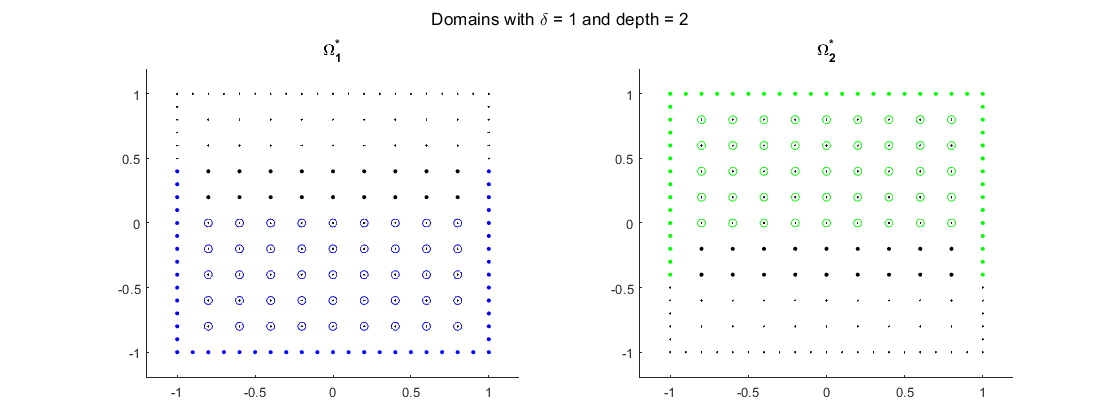

delta = 1;

Interface = find(Points(Interior,2)==0); % points in the interior that lie on the artificial interface

Interior1 = Interior(Points(Interior,2)<0);
Interior2 = Interior(Points(Interior,2)>0);
Boundary1 = Boundary(Points(Boundary,2)<=0);
Boundary2 = Boundary(Points(Boundary,2)>=0);

Boundary1 = Boundary(Points(Boundary,2) <= h*(delta+depth-1)); % extend upward
Boundary2 = Boundary(Points(Boundary,2) >= -h*(delta+depth-1)); % extend downward

Interface1 = [Interface+N*delta; Interface+N*2];
Interface2 = [Interface-N*delta; Interface-N*2];

for i = 1:delta
    Interior1 = [Interior1, Interface'+N*(i-1)];
    Interior2 = [Interior2, Interface'-N*(i-1)];
end

figure
subplot(121)
scatter(Points(:,1),Points(:,2),1,'k')
hold on
scatter(Points(Interior1,1),Points(Interior1,2),[],c1)
scatter(Points(Boundary1,1),Points(Boundary1,2),10,c1,"filled")
scatter(Points(Interface1,1),Points(Interface1,2),10,"black","filled")
axis(lims)
title('\Omega_1^{*}')

subplot(122)
scatter(Points(:,1),Points(:,2),1,'k')
hold on
scatter(Points(Interior2,1),Points(Interior2,2),[],c2)
scatter(Points(Boundary2,1),Points(Boundary2,2),10,c2,'filled')
scatter(Points(Interface2,1),Points(Interface2,2),10,"black","filled")
axis(lims)
title('\Omega_2^{*}')
sgtitle("Domains with \delta = "+delta+" and depth = "+depth)
set(gcf,'position',[1001  559  2*560  420])

The solid points are boundary points and the open circles are interior points. The solid colored points correspond to ${\Sigma_i }^h$ and the solid black points correspond to $\Sigma_{\textrm{ij}}^h$.

## Solving a local problem

The `NMatSSD` matrix is constructed based on the global indeces of nodes, i.e. the indeces are numbered from 1 to $N_p$.  It cannot be used to solve a local problem as it is. 

We need a way to map global indexing to the local indexing. The discrete global solution $u^h$ has dimension $N_p$. The first $N_i$ entries of $u^h$ correspond to interior node solution. The entries from $N_i +1$to $N_i +N_b$ correspond to the boundary solution. (Some boundary nodes are repeated - this is a bug).  We will assume the discrete local solutions $u_i^h$ are ordered in a similar way. The will order it so that the local solutions have interior nodes, exterior boundary nodes, and then artificial boundary nodes. 

One way to solve this indexing issue is to create local version of the `NMatSSD` matrix. Here is the algorithm to construct it:

`    1. Create an index from the local indexing to the global index: g2l = [Interior1, Boundary1, Interface1]`

`    2. Extract the rows of NMatSSD corresponding to Interior1: NMatLoc = NMatSSD(Interior1,:) `

`    3. Loop over each elem in NMatLoc`

`        Find the index of elem in g2l vector `

`        Repclace elem with index`

Once the local version of the matrix is constructed, it can be passed into `quadSolver`. 

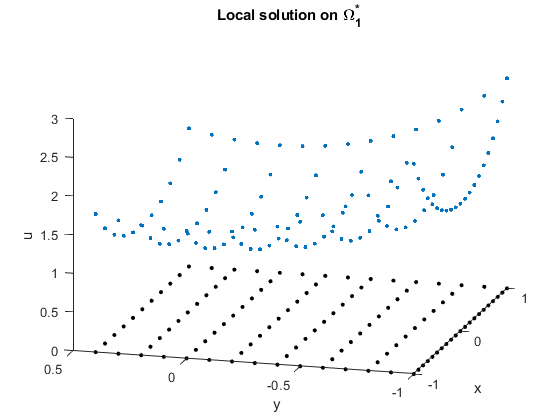

order = 1;
epsilon = h^2;
weight = quadWeights(theta,order);
% Parameters needed to solve problem

DirBC = @(x,y) (exp((x.^2+y.^2)/2));
contF = @(x,y) ((1+x.^2+y.^2).*exp(x.^2+y.^2));

F = contF(Points(Interior1,1),Points(Interior1,2)); % compute rhs at interior pts

uBdry = DirBC(Points(Boundary1,1),Points(Boundary1,2)); % compute g at exterior bdry

uBdry = [uBdry; DirBC(Points(Interface1,1),Points(Interface1,2))]; % compute g at interface

% construct local matrix
NMatLoc = NMatSDD(Interior1,:);
local2global = [Interior1'; Boundary1; Interface1];
for i = 1:length(Interior1)
    for j = 1:3*Ns
        ind = NMatLoc(i,j);
        loc = find(ind == local2global);
        NMatLoc(i,j) = loc;
    end
end


[uSoln, perf] = quadSolver(NMatLoc,CMatSDD(Interior1,:),F,uBdry,epsilon,weight,h); % call solver
% Solve with newton's method and no given initial guess.

figure
plot3(Points(local2global,1),Points(local2global,2),uSoln,'.')
hold on
scatter(Points(local2global,1),Points(local2global,2),10,'k','filled')
xlabel('x'), ylabel('y'), zlabel('u')
title('Local solution on \Omega_1^*')

The plot above shows the output of the `quadSolver` routine for the mesh restricted to $\Omega_1^*$.

## Swapping Data

In order to swap data to neighboring domains, you need to know whch local-to-local indexing. 

We are using a highly regular domain. We will implement a swapping mechanism that is particular to this geometry. 

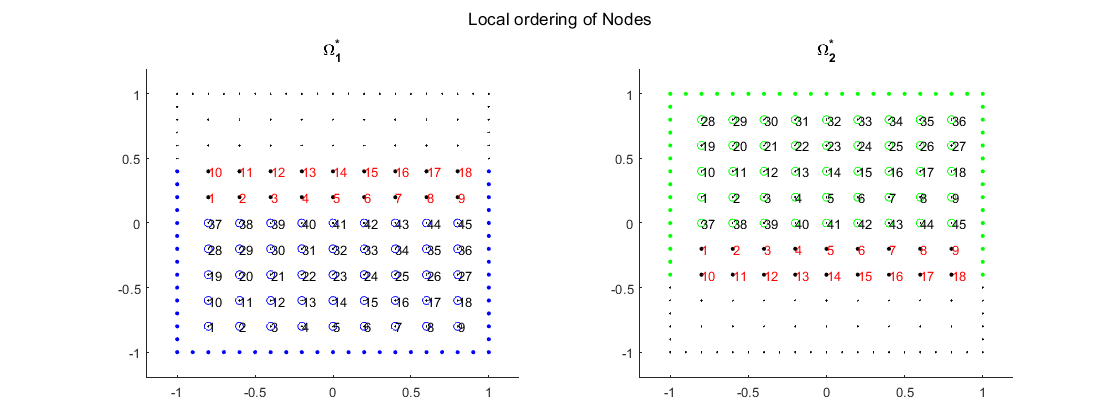


figure
subplot(121)
scatter(Points(:,1),Points(:,2),1,'k')
hold on
scatter(Points(Interior1,1),Points(Interior1,2),[],c1)
scatter(Points(Boundary1,1),Points(Boundary1,2),10,c1,"filled")
scatter(Points(Interface1,1),Points(Interface1,2),10,"black","filled")
for i = 1:length(Interior1)
    text(Points(Interior1(i),1),Points(Interior1(i),2),num2str(i))
end
for i = 1:length(Interface1)
    text(Points(Interface1(i),1),Points(Interface1(i),2),num2str(i),'color','r')
end
axis(lims)
title('\Omega_1^{*}')

subplot(122)
scatter(Points(:,1),Points(:,2),1,'k')
hold on
scatter(Points(Interior2,1),Points(Interior2,2),[],c2)
scatter(Points(Boundary2,1),Points(Boundary2,2),10,c2,'filled')
scatter(Points(Interface2,1),Points(Interface2,2),10,"black","filled")
for i = 1:length(Interior2)
    text(Points(Interior2(i),1),Points(Interior2(i),2),num2str(i))
end
for i = 1:length(Interface2)
    text(Points(Interface2(i),1),Points(Interface2(i),2),num2str(i),'color','r')
end
axis(lims)
title('\Omega_2^{*}')
sgtitle("Local ordering of Nodes")
set(gcf,'position',[1001  559  2*560  420])

The plot above shows how the interior nodes and the artificial interfaces are enumerated. 

- The artificial interface nodes for domain 1 correspond to interior nodes 1 to 9 and 10 to 18 of domain 2.

- The artificial interface nodes for domain 2 correspond to interior nodes 28 to 36 and 19 to 27 of domain 1.  

The indeces of the nodes to be swapped can be expressed in term of $N$(the number of interior nodes per row). We again assume $N$ is odd. Row $\frac{N+1}{2}$ is the original location of the artificial interface. 

- Domain 2 sends $1\;\textrm{to}\;N$, and $N+1\;\textrm{to}\;2N$

- Domain 1 sends $1+\left(\frac{N-1}{2}-1\right)N\;\textrm{to}\;\frac{N-1}{2}N$ and $1+\left(\frac{N-1}{2}-2\right)N\;\textrm{to}\;\left(\frac{N-1}{2}-1\right)N$. 

send1 = [1+(N-3)/2*N:(N-1)/2*N,  (1+(N-5)/2*N):(N-3)/2*N]

send1 =     28    29    30    31    32    33    34    35    36    19    20    21    22    23    24    25    26    27


send2 = 1:2*N

send2 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18


## Schwarz Iteration 

In this section, we will run a few iterations of the SAP.

#### Create the local NMatSSD 

% construct local matrices 
NMatLoc1 = NMatSDD(Interior1,:);
local2global1 = [Interior1'; Boundary1; Interface1];
for i = 1:length(Interior1)
    for j = 1:3*Ns
        ind = NMatLoc1(i,j);
        loc = find(ind == local2global1);
        NMatLoc1(i,j) = loc;
    end
end

NMatLoc2 = NMatSDD(Interior2,:);
local2global2 = [Interior2'; Boundary2; Interface2];
for i = 1:length(Interior2)
    for j = 1:3*Ns
        ind = NMatLoc2(i,j);
        loc = find(ind == local2global2);
        NMatLoc2(i,j) = loc;
    end
end

#### Initialize the data 

u1 = [zeros(length(Interior1),1); zeros(length(Boundary1),1); zeros(length(Interface1),1)];
F1 = contF(Points(Interior1,1),Points(Interior1,2));     % compute rhs at interior pts
uBdry1 = DirBC(Points(Boundary1,1),Points(Boundary1,2)); % compute g 
uBdry1 = [uBdry1; zeros(length(Interface1),1)];          % space for interface 
N12 = length(Interface1);

u2 = [zeros(length(Interior2),1); zeros(length(Boundary2),1); zeros(length(Interface2),1)];
F2 = contF(Points(Interior2,1),Points(Interior2,2));     % compute rhs at interior pts
uBdry2 = DirBC(Points(Boundary2,1),Points(Boundary2,2)); % compute g 
uBdry2 = [uBdry2; zeros(length(Interface2),1)];          % space for interface 
N21 = length(Interface2);

#### DDM Iteration

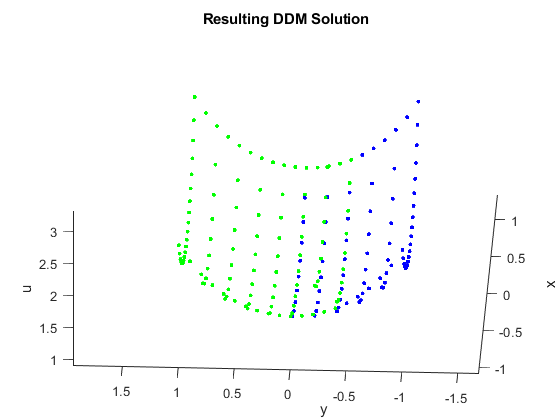

N_iter = 100;

for k = 1:N_iter
    
    % Step 1: prepare uBdry 
    uBdry2(end-N12+1:end) = u1(send2); 
    uBdry1(end-N21+1:end) = u2(send2);
    
    % Step 2: solve 
    [u1, ~] = quadSolver(NMatLoc1,CMatSDD(Interior1,:),F1,uBdry1,epsilon,weight,h); % call solver
    [u2, ~] = quadSolver(NMatLoc2,CMatSDD(Interior2,:),F2,uBdry2,epsilon,weight,h); % call solver
end


figure
plot3(Points(local2global1,1),Points(local2global1,2),u1,'.','Color',c1)
hold on
plot3(Points(local2global2,1),Points(local2global2,2),u2,'.','Color',c2)
xlabel('x'), ylabel('y'), zlabel('u')
title('Resulting DDM Solution')

The solutions of $u_1$ and $u_2$ after a few iterations is plotted above. It appears to be converging. 